directory = 'D:\Vincent\Data\sc012\sc012_0123';
session = Session(directory);

Searching directory:  D:\Vincent\Data\test\test4 
Found recording format: Binary 
Detected 3 recordings 


% session.show()

Get raw data recording node 

node = session.recordNodes{1,1};
recording=node.recordings{1,1};
recording.continuous.keys()

ans = 1×3 cell array
    {'NI-DAQmx-109.PXIe-6341'}    {'Neuropix-PXI-100.ProbeA-AP'}    {'Neuropix-PXI-100.ProbeA-LFP'}


Get data from AP data stream

APData=recording.continuous('Neuropix-PXI-100.ProbeA-AP');
sampleData=APData.samples(10,1:3*10^5);

Plot sample data

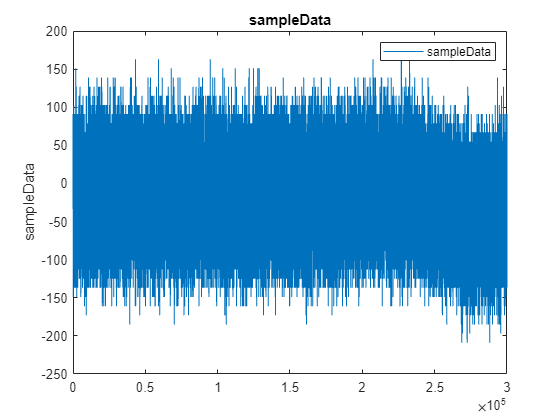

% Create plot of sampleData
h = plot(sampleData,"DisplayName","sampleData");

% Add ylabel, title, and legend
ylabel("sampleData")
title("sampleData")
legend

Get TTL data

TTLs=node.recordings{1,1}.ttlEvents('NI-DAQmx-109.PXIe-6341');
CamTS{1}=TTLs.timestamp(TTLs.line==2);
CamTS{1}=CamTS{1}(TTLs.state(TTLs.line==2));
% numel(CamTS{1})
TTLs=node.recordings{1,2}.ttlEvents('NI-DAQmx-109.PXIe-6341');
CamTS{2}=TTLs.timestamp(TTLs.line==2);
CamTS{2}=CamTS{2}(TTLs.state(TTLs.line==2));
% numel(CamTS{2})
TTLs=node.recordings{1,3}.ttlEvents('NI-DAQmx-109.PXIe-6341');
CamTS{3}=TTLs.timestamp(TTLs.line==2);
CamTS{3}=CamTS{3}(TTLs.state(TTLs.line==2));
% numel(CamTS{3})
numel(vertcat(CamTS{:}))

ans = 19222